# Invers Kinematics: Key ideas

## Call a simple Two Link 

2R robot arm

Type at command window 'models' to see all the RTB Manipulators object models

clear
mdl_twolink
twolink

 
twolink = 
 
two link:: 2 axis, RR, stdDH, slowRNE                            
 - from Spong, Hutchinson, Vidyasagar;                           
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          1|          0|          0|
|  2|         q2|          0|          1|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
base:    t = (0, 0, 0), RPY/xyz = (0, 0, 90) deg                 
 


### Plotting twolink

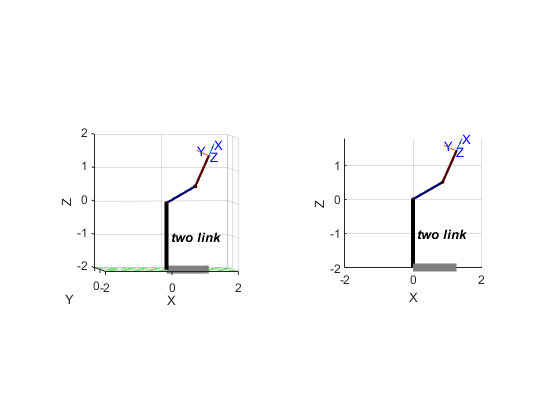

subplot(121)
twolink.plot([pi/6 pi/5],'view',[-40 25],'zoom',2)
subplot(122)
view (0, 0)
twolink.plot([pi/6 pi/5],'zoom',2)
axis([-0.5 2 -0.5 0.5 -0.5 2.5])
axis equal
view (0, 0)

### Forward Kinematics of Two Link

syms theta_1 theta_2 L_1 L_2 real
FK2L_Hand=simplify(troty(theta_1)*transl(L_1,0,0)*troty(theta_2)*transl(L_2,0,0))

$$FK2L\_Hand = \left(\begin{array}{cccc} \cos\left(\theta_{1}+\theta_{2}\right) & 0 & \sin\left(\theta_{1}+\theta_{2}\right) & L_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+L_{1}\,\cos\left(\theta_{1}\right)\\ 0 & 1 & 0 & 0\\ -\sin\left(\theta_{1}+\theta_{2}\right) & 0 & \cos\left(\theta_{1}+\theta_{2}\right) & -L_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)-L_{1}\,\sin\left(\theta_{1}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

twolink.links(1, 1).a=L_1;
twolink.links(1, 2).a=L_2;
FK2L_RTB=simplify(twolink.fkine ([theta_1 theta_2]))

$$\left(\begin{array}{cccc} \cos\left(\theta_{1}+\theta_{2}\right) & -\sin\left(\theta_{1}+\theta_{2}\right) & 0 & L_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+L_{1}\,\cos\left(\theta_{1}\right)\\ 0 & 0 & -1 & 0\\ \sin\left(\theta_{1}+\theta_{2}\right) & \cos\left(\theta_{1}+\theta_{2}\right) & 0 & L_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)+L_{1}\,\sin\left(\theta_{1}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

### The equation system to solve

syms x z real %position of the {EE}
e1 = x == FK2L_RTB.t(1)

$$e1 = x=L_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+L_{1}\,\cos\left(\theta_{1}\right)$$

e2 = z == FK2L_RTB.t(3)

$$e2 = z=L_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)+L_{1}\,\sin\left(\theta_{1}\right)$$

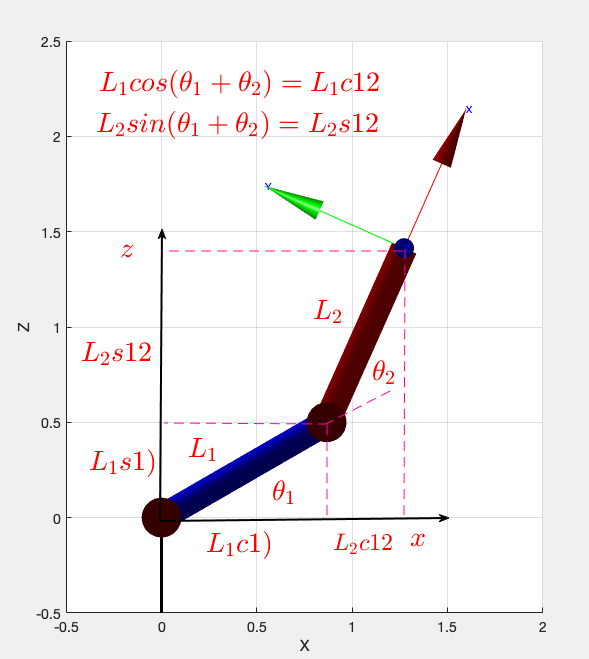

## Invers Kinematics by hand.

### Generate a known solution

clear
mdl_twolink
q1=pi/6

q1 = 0.5236

q2=pi/5

q2 = 0.6283

twolink.links(1, 1).a=1.5;
twolink.links(1, 2).a=1;
FD=twolink.fkine([q1 q2]);
XYZ=FD.t

XYZ =     1.7058
         0
    1.6635


Rotation=FD.R

Rotation =     0.4067   -0.9135         0
         0         0   -1.0000
    0.9135    0.4067         0


c=cos(q1+q2)

c = 0.4067

s=sin(q1+q2)

s = 0.9135

L1=twolink.links(1, 1).a

L1 = 1.5000

L2=twolink.links(1, 2).a

L2 = 1

### Apply the theory

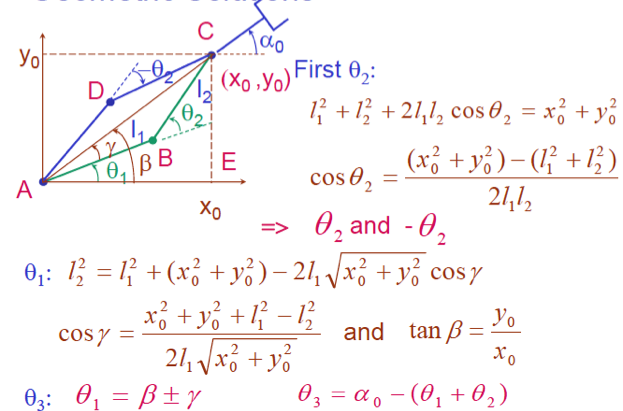

theta_2=acos(((XYZ(1)^2+XYZ(3)^2) -(L1^2+L2^2))/(2*L1*L2))

theta_2 = 0.6283

q2

q2 = 0.6283

beta=atan2(XYZ(3),XYZ(1))

beta = 0.7729

gamma=acos((XYZ(1)^2+XYZ(3)^2+L1^2-L2^2)/(2*L1*sqrt((XYZ(1)^2+XYZ(3)^2))))

gamma = 0.2493

theta_1_1=beta+gamma

theta_1_1 = 1.0221

theta_1_2=beta-gamma

theta_1_2 = 0.5236

q1

q1 = 0.5236

### Testing solutions. See {EE}

XYZ

XYZ =     1.7058
         0
    1.6635


FD=twolink.fkine([q1 q2]);
FD_1=twolink.fkine([theta_1_1 -theta_2])

 

FD_1 = 
    0.9235   -0.3837         0     1.706
         0         0        -1         0
    0.3837    0.9235         0     1.664
         0         0         0         1


FD_2=twolink.fkine([theta_1_2 +theta_2])

 

FD_2 = 
    0.4067   -0.9135         0     1.706
         0         0        -1         0
    0.9135    0.4067         0     1.664
         0         0         0         1


### Plotting both solutions

First clone twolink

twolink_2= SerialLink(twolink, 'name', '2L_2'); % clone twolink 

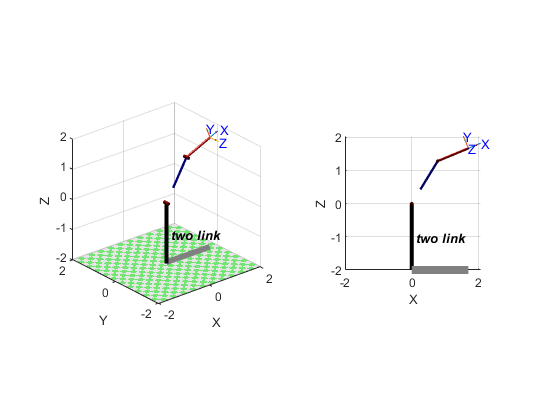

figure
twolink.plot([theta_1_1 -theta_2],'zoom',2)

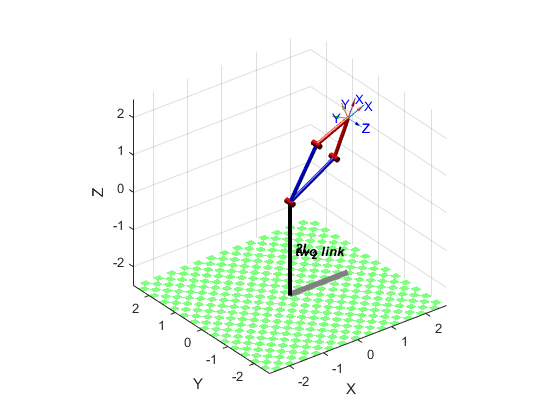

hold on
twolink_2.plot([theta_1_2 +theta_2],'zoom',2)

## Invers Kinematics using RTB

At command windows: 

help SerialLink/ikine

### Generate a known solution

%mdl_twolink

FD=twolink.fkine([q1 q2])

 

FD = 
    0.4067   -0.9135         0     1.706
         0         0        -1         0
    0.9135    0.4067         0     1.664
         0         0         0         1


### Invoque ikine function

At command windows: help SerialLink/ikine to know more...it is a recursive numerical approach

and remember

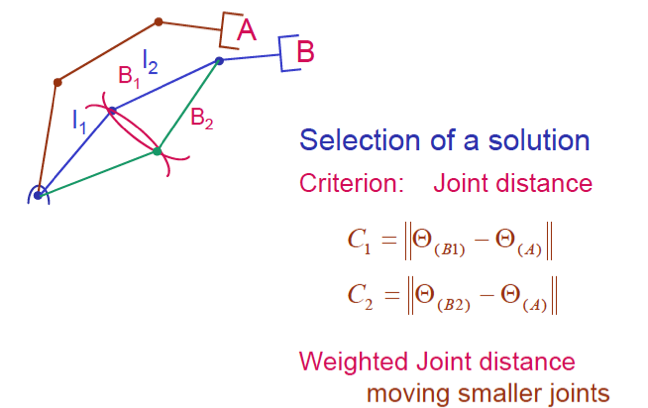

#### Elbow down

Qd=twolink.ikine(FD,'mask',[1 1 0 0 0 0 ], 'q0',[0 0])

Qd =     0.5236    0.6283


q1q2=[q1 q2]

q1q2 =     0.5236    0.6283


sol1=[theta_1_2 theta_2]

sol1 =     0.5236    0.6283


#### Elbow up

Qu=twolink.ikine(FD,'mask',[1 1 0 0 0 0 ], 'q0',[pi/2 0])

Qu =     1.0221   -0.6283


sol2=[theta_1_1 theta_2]

sol2 =     1.0221    0.6283


### Ploting both solutions

Clone the twolink

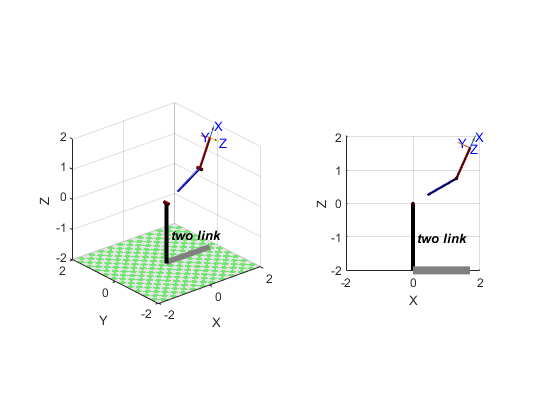

subplot(121)
twolink.plot(Qd)
axis([-0.5 2 -0.5 0.5 -0.5 2.5])
axis equal
view (0, 0)
subplot(122)
twolink_2.plot(Qu)

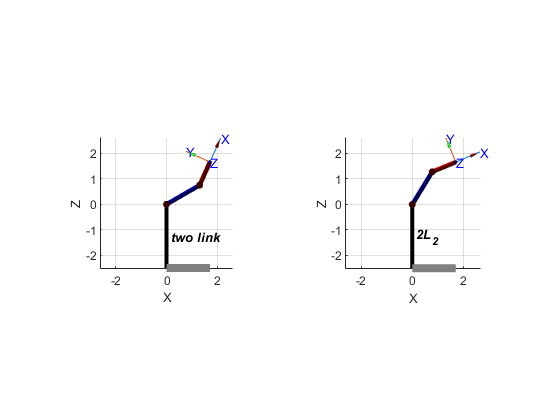

axis([-0.5 2 -0.5 0.5 -0.5 2.5])
axis equal
view (0, 0)

## Inverse Kinematics of Puma560

At command windows: 

help SerialLink/ikine6s

clear
mdl_puma560
bob= SerialLink(p560, 'name', 'bob'); % clone puma 560
bob1= SerialLink(p560, 'name', 'bob1'); % clone puma 560
bob2= SerialLink(p560, 'name', 'bob2'); % clone puma 560
qn 

qn =          0    0.7854    3.1416         0    0.7854         0


T1 = p560.fkine(qn)

 

T1 = 
         0         0         1    0.5963
         0         1         0   -0.1501
        -1         0         0  -0.01435
         0         0         0         1


Chose different solutions

qi1 = p560.ikine6s(T1,'ru')

qi1 =    -0.0000    0.7854    3.1416   -0.0000    0.7854    0.0000


qi2 = p560.ikine6s(T1,'rd')

qi2 =    -0.0000   -0.8335    0.0940   -3.1416    0.8312    3.1416


qi3 = p560.ikine6s(T1,'lu')

qi3 =     2.6486   -3.9270    0.0940    2.5326    0.9743    0.3734


qi4 = p560.ikine6s(T1,'ld')

qi4 =     2.6486   -2.3081    3.1416    0.6743    0.8604    2.6611


T2 = p560.fkine(qi1) % is equal to T1 close all!!!

 

T2 = 
         0         0         1    0.5963
         0         1         0   -0.1501
        -1         0         0  -0.01435
         0         0         0         1


T3 = p560.fkine(qi2) % is equal to T1 !!!

 

T3 = 
         0         0         1    0.5963
         0         1         0   -0.1501
        -1         0         0  -0.01435
         0         0         0         1


T4 = p560.fkine(qi3) % is equal to T1 close all!!!

 

T4 = 
         0         0         1    0.5963
         0         1         0     -0.15
        -1         0         0  -0.01435
         0         0         0         1


T5 = p560.fkine(qi4) % is equal to T1 close all!!!

 

T5 = 
         0         0         1    0.5963
         0         1         0     -0.15
        -1         0         0  -0.01435
         0         0         0         1


T1

 

T1 = 
         0         0         1    0.5963
         0         1         0   -0.1501
        -1         0         0  -0.01435
         0         0         0         1


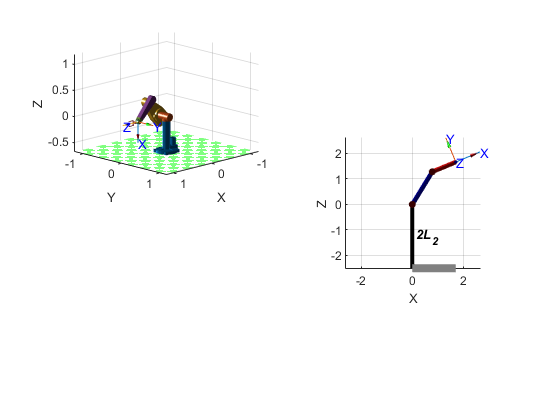

Loading STL models from ARTE Robotics Toolbox for Education  by Arturo Gil (http://arvc.umh.es/arte).......



subplot(221)
p560.plot3d(qi1)

subplot(222)
bob.plot3d(qi2)

Loading STL models from ARTE Robotics Toolbox for Education  by Arturo Gil (http://arvc.umh.es/arte).......


subplot(223)
bob1.plot3d(qi3)

Loading STL models from ARTE Robotics Toolbox for Education  by Arturo Gil (http://arvc.umh.es/arte).......


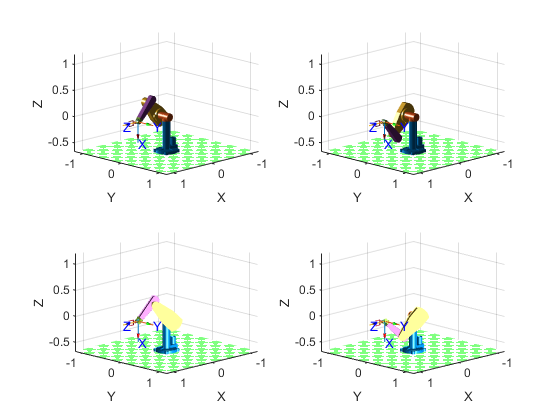

Loading STL models from ARTE Robotics Toolbox for Education  by Arturo Gil (http://arvc.umh.es/arte).......


subplot(224)
bob2.plot3d(qi4)

## Practicing with ikine6s & p560.plot3d(qx)

Display the 8 solutions for qn (joint space). Use subplot 2x2 for elbown up/down and subplot 2x2 for {EE}